# Flow in complex domains

clear, close all, clc
set_demo_defaults
col = marc_colors();

## Crater in a square domain

Consider the simple example of a square unit domain with a circulr crater of radius $R_c$ in the center. We have a regular 2D cartesian grid as shown in the figure.

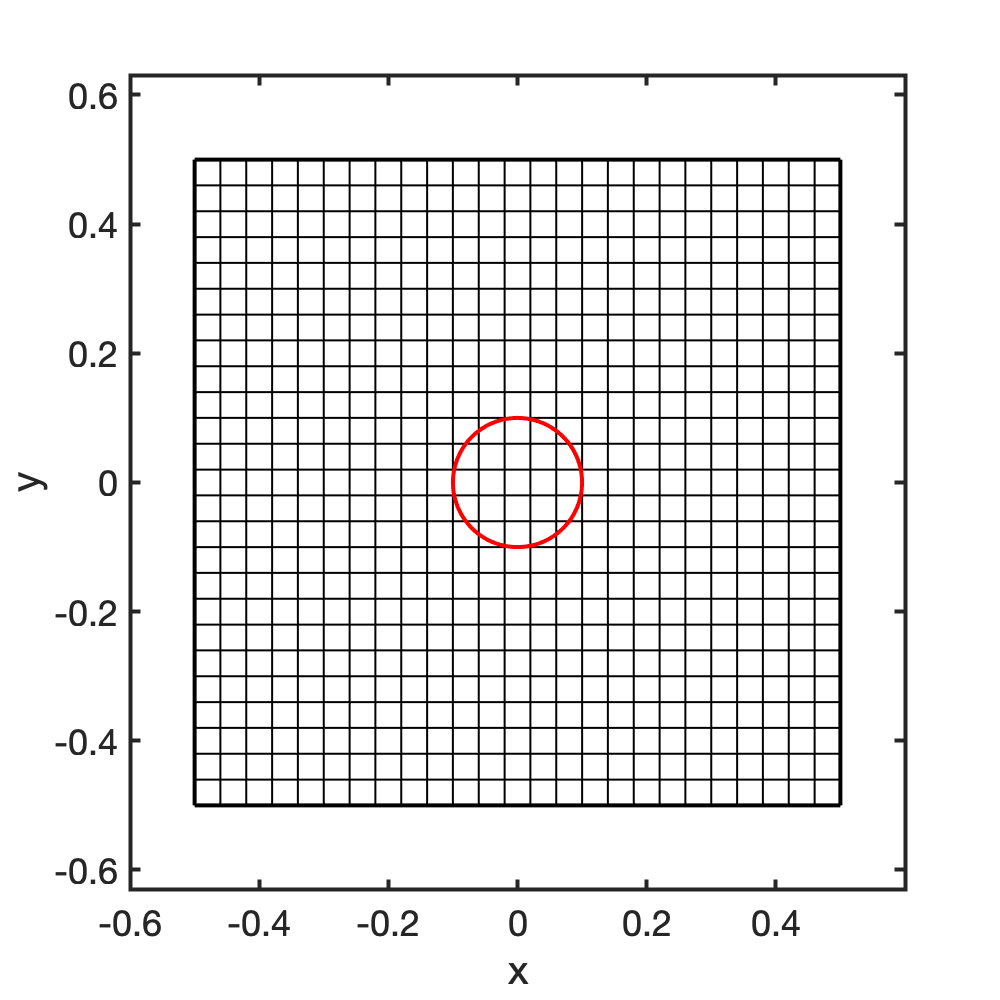

x0  = [0];
y0  = [0];
Rc = [.1];

Pi_out = 0.3;
Pi_crater = 0.2;

Grid.xmin = -1/2; Grid.xmax = 1/2; Grid.Nx = 25;
Grid.ymin = -1/2; Grid.ymax = 1/2; Grid.Ny = 25;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);

figure('position',[10 10 500 500])
plot([Grid.xf';Grid.xf'],[Grid.ymin*ones(1,Grid.Nx+1);Grid.ymax*ones(1,Grid.Nx+1)],'k','linewidth',1), hold on
plot([Grid.xmin*ones(1,Grid.Ny+1);Grid.xmax*ones(1,Grid.Ny+1)],[Grid.yf';Grid.yf'],'k','linewidth',1)
plot_circle(x0,y0,Rc)
plot(Grid.xdom,Grid.ydom,'k-')
xlim([-1 1]*.6), ylim([-1 1]*.6)
axis equal
xlabel 'x', ylabel 'y'

## Modify domain to cut out crater

Below we show the steps that are necessary to cut the crater from the domain and impose new boundary conditions along it. 

## Step 1: Find cells in the crater

Here we will refer to the cells in the crater that we want to remove as **inactive cells** and the remaining cells outside the crater at **active cells**.

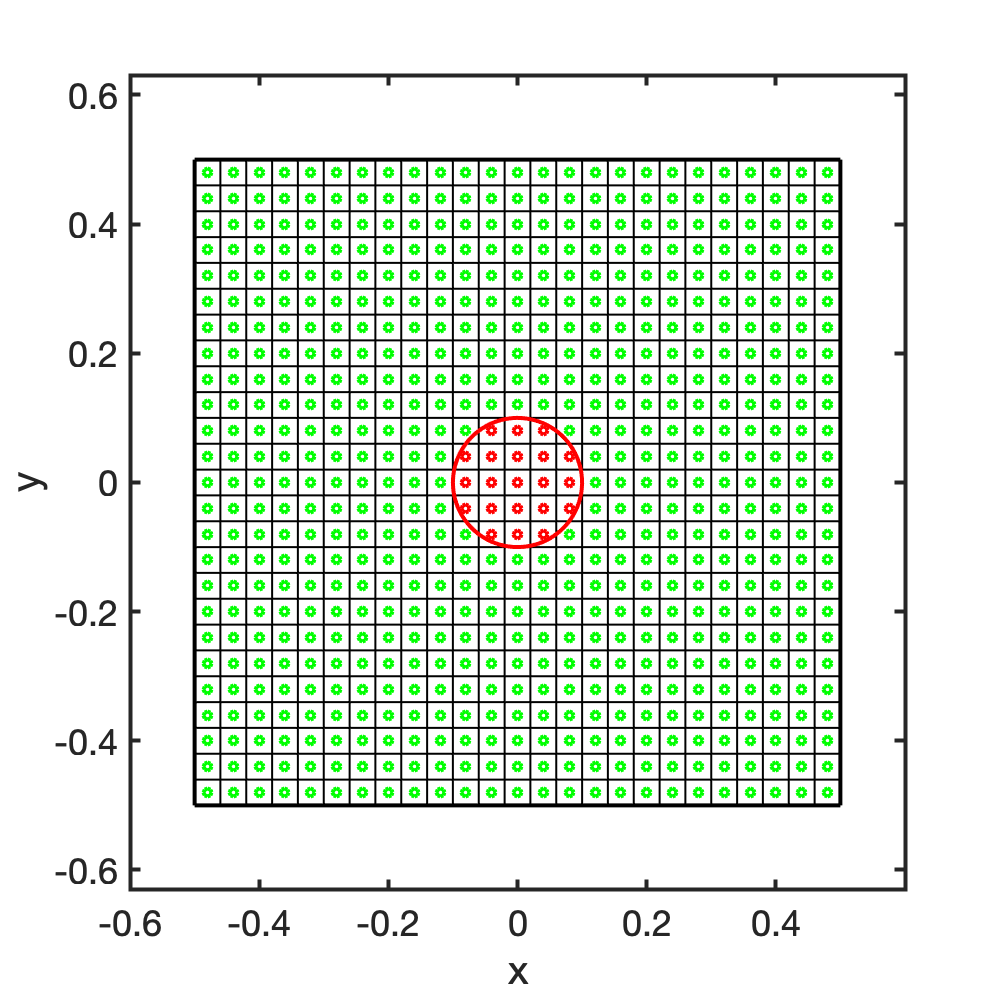

[dof_inact,dof_act] = find_crater_dofs(x0,y0,Rc,Grid,Xc,Yc);

figure('position',[10 10 500 500])
plot([Grid.xf';Grid.xf'],[Grid.ymin*ones(1,Grid.Nx+1);Grid.ymax*ones(1,Grid.Nx+1)],'k','linewidth',1), hold on
plot([Grid.xmin*ones(1,Grid.Ny+1);Grid.xmax*ones(1,Grid.Ny+1)],[Grid.yf';Grid.yf'],'k','linewidth',1)
plot(Xc(dof_inact),Yc(dof_inact),'ro','markersize',4)
plot(Xc(dof_act),Yc(dof_act),'go','markersize',4)
plot_circle(x0,y0,Rc)
plot(Grid.xdom,Grid.ydom,'k-')
xlim([-1 1]*.6), ylim([-1 1]*.6)
axis equal
xlabel 'x', ylabel 'y'

## Step 2: Find the boundary of the crater

Now we need to find the faces that bound the inactive cells inside the crater.

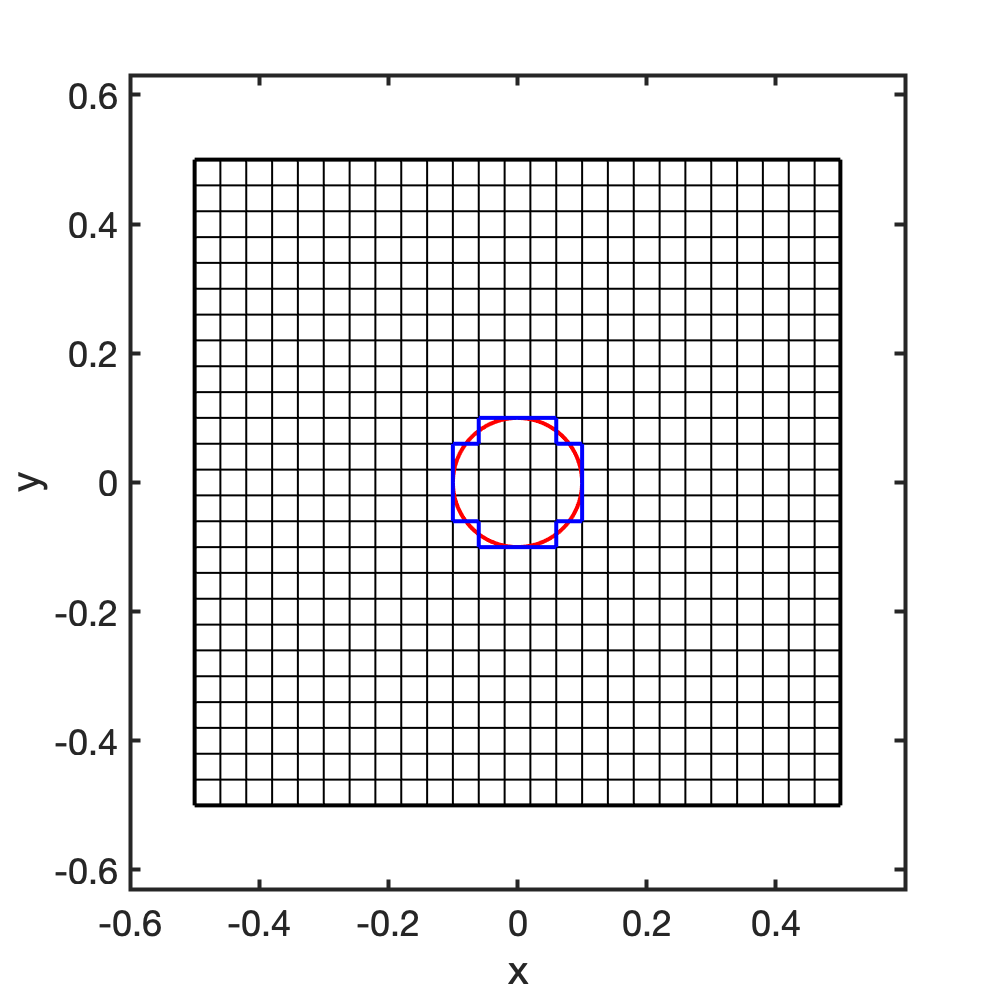

dof_f_crater = find_faces(dof_inact,D,Grid);
[X_f_crater,Y_f_crater] = comp_face_coords(dof_f_crater,Grid);

figure('position',[10 10 500 500])
plot([Grid.xf';Grid.xf'],[Grid.ymin*ones(1,Grid.Nx+1);Grid.ymax*ones(1,Grid.Nx+1)],'k','linewidth',1), hold on
plot([Grid.xmin*ones(1,Grid.Ny+1);Grid.xmax*ones(1,Grid.Ny+1)],[Grid.yf';Grid.yf'],'k','linewidth',1)
plot_circle(x0,y0,Rc)
plot(X_f_crater,Y_f_crater,'-','color','b','linewidth',2)
plot(Grid.xdom,Grid.ydom,'k-')
xlim([-1 1]*.6), ylim([-1 1]*.6)
axis equal
xlabel 'x', ylabel 'y'

## Step 3: Find the cells along the boundary

To impose the dirichlet boundary conditions along the crater we need the cells that are along the boundary. Since there are two sides of the boundary, we get two arrays one with the cells in the active domain and one with the cells in the inactive domain.

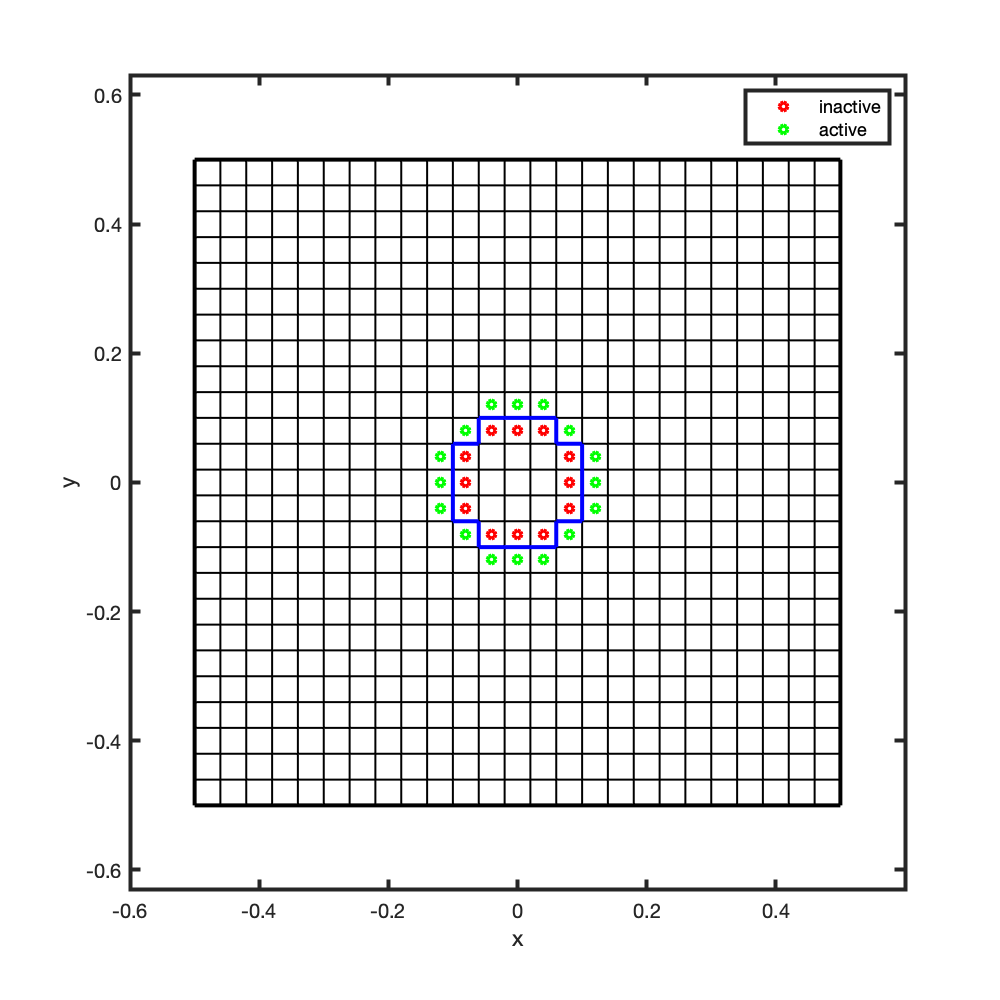

[dof_bnd_act,dof_bnd_inact] = find_bnd_cells(dof_act,dof_inact,dof_f_crater,D,Grid);

figure('position',[10 10 500 500])
plot(Xc(dof_bnd_inact),Yc(dof_bnd_inact),'ro','markersize',4), hold on
plot(Xc(dof_bnd_act),Yc(dof_bnd_act),'go','markersize',4)
plot([Grid.xf';Grid.xf'],[Grid.ymin*ones(1,Grid.Nx+1);Grid.ymax*ones(1,Grid.Nx+1)],'k','linewidth',1), hold on
plot([Grid.xmin*ones(1,Grid.Ny+1);Grid.xmax*ones(1,Grid.Ny+1)],[Grid.yf';Grid.yf'],'k','linewidth',1)
plot(X_f_crater,Y_f_crater,'-','color','b','linewidth',2)
plot(Grid.xdom,Grid.ydom,'k-')
xlim([-1 1]*.6), ylim([-1 1]*.6)
axis equal
xlabel 'x', ylabel 'y'
legend('inactive','active')

## Solve confined flow with crater lake

## Governing equations

As a first example lets look at confined flow with precipitation and sea level applied at the right side. The crater in the center has a late level that is prescribed independently from sea level. Assuming a constant hydraulic conductivity, the dimensionless problem is given by

PDE: $-\nabla\cdot\nabla h' = q_p$   on $x\in\left[-\frac{1}{2},\,\frac{1}{2}\right]\times y\in \left[-\frac{1}{2},\,\frac{1}{2}\right]$

BC's: $h'(x'=\frac{1}{2},y')=\Pi_b$ and $\left.h'\right|_{\partial\Omega_{crater}} = \Pi_{c}$

where $\partial\Omega_{crater}$ is the boundary of the crater. All other boundaries are natural, i.e., no flow.

## Refined mesh

Above we used a cery coarse mesh to illustrate the identification of cells and faces. For the simulations we use a finer mesh

Grid.xmin = -1/2; Grid.xmax = 1/2; Grid.Nx = 250;
Grid.ymin = -1/2; Grid.ymax = 1/2; Grid.Ny = 250;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
fs = ones(Grid.N,1);
M = Grid.dx/2*abs(G);    % mean operator
if Grid.dx ~= Grid.dy; error('dx~=dy: need to update M!\n'); end

Find the crater related arrays

[dof_inact,dof_act] = find_crater_dofs(x0,y0,Rc,Grid,Xc,Yc);
dof_f_crater = find_faces(dof_inact,D,Grid);
[dof_bnd_act,dof_bnd_inact] = find_bnd_cells(dof_act,dof_inact,dof_f_crater,D,Grid);
N_crater = length(dof_bnd_act);

## Step 1: Modify gradient to impose natural BC at crater

The standard gradient will compute the derivative of the head at all boundaries. For this boundary to behave as any other we need to set the gradient along the crater to zero. this is simple

G(dof_f_crater,:) = 0; % Natural boundary conditions at crater

Note, this cuts the mesh into two regions that are not connected. If we tried to solve

## Step 2: Eliminate the inactive cells with constraints

To avoid an ill-conditioned system and to reduce the computational work we eliminate the inactive cells using constraints.

We simply add them to the constraint matrix B and set them to NaN.

%% Eliminate inactive cells
BC.dof_dir   = [Grid.dof_xmax;... % Outflow BC's
                dof_bnd_act;...    % Crater bnd
                dof_inact];       % Inactive cells
BC.dof_f_dir = [Grid.dof_f_xmax;...
                dof_f_crater];
BC.g = [Pi_out*ones(Grid.Ny,1);...
        Pi_crater*ones(N_crater,1);...
       -NaN(size(dof_inact))];
[B,N,fn] = build_bnd(BC,Grid,I);

## Step 3: Solve PDE with additional constraints

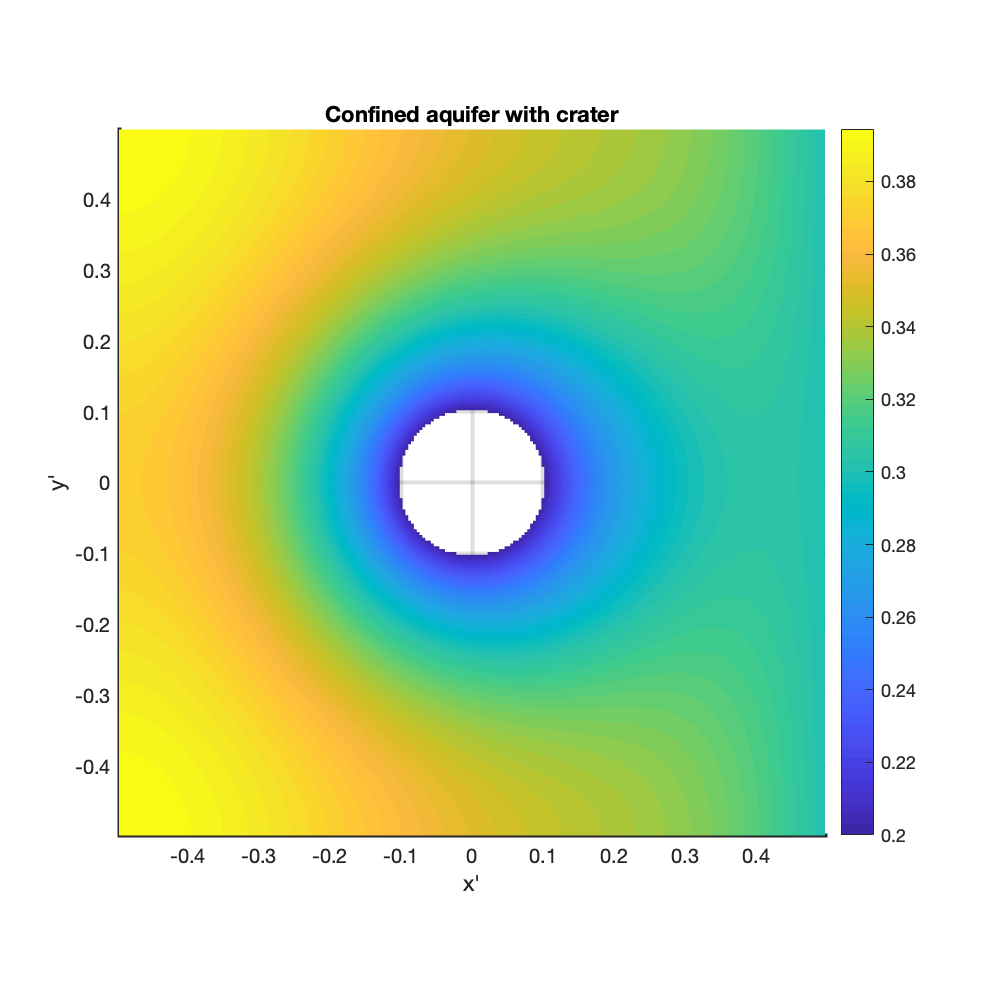

L = -D*G;  fs = ones(Grid.N,1);
hD_conf = solve_lbvp(L,fs + fn,B,BC.g,N);

figure('position',[10 10 500 500])
surf(Xc,Yc,reshape(hD_conf,Grid.Ny,Grid.Nx)), view(2), shading interp, colorbar
xlabel 'x'''
ylabel 'y'''
title 'Confined aquifer with crater'
axis equal tight

## Solve unconfined flow with crater lake

Changing from confined to unconfined flow only requires a few changes.

## Step 1: Define residual vector and Jacobian matrix

n_exp = 5;
[res,Jac] = steady_dupuit_res_jac(Grid,D,G,M,fs,fn,n_exp);

## Step 2: Update the BC's 

In the Newton-Raphson method we set boundary conditions for the update rather than the solutions. Hence we need to update the boundary conditions

BC.dof_dir   = [Grid.dof_xmax;... % Outflow BC's
                dof_bnd_act;...    % Crater bnd
                dof_inact];       % Inactive cells
BC.dof_f_dir = [Grid.dof_f_xmax;...
                dof_f_crater];
BC.g = [zeros(Grid.Ny,1);...
        zeros(N_crater,1);...
       -NaN(size(dof_inact))];
[B,N,fn] = build_bnd(BC,Grid,I);

## Step 3: Define initial guess

In this case we can just use the confined head as an initial guess for the unconfined head. It already satisfies the Dirichlet boundary condition on the right side.

hD = hD_conf;

## Step 4: Solve with Newton-Raphson method

%% Newton iteration
tol = 1e-6; % convergence tolerance
kmax = 20;  % maximum number of iterations

% Initial guess
hD = ones(Grid.N,1);
hD(BC.dof_dir) = Pi_out; % satisfy Dir BC so dhD = 0 on bnd!
hD(dof_bnd_act) = Pi_crater;

nres = norm(res(hD)); ndhD = 1; k = 0;
fprintf('Newton-Raphson method:\n')

Newton-Raphson method:


while (nres > tol || ndhD > tol) && k < kmax
    dhD = solve_lbvp(Jac(hD),-res(hD),B,BC.g,N);
    hD = hD + dhD;
    nres = norm(N'*res(hD)); ndhD = norm(N'*dhD);
    k = k+1;
    fprintf('it = %d: nres = %3.2e  ndhD = %3.2e\n',k,nres,ndhD)
    if k == 1; ndhD = 0; end % to allow exit on first iteration
end

it = 1: nres = 3.24e+04  ndhD = 1.25e+02
it = 2: nres = 1.07e+04  ndhD = 3.67e+01
it = 3: nres = 3.16e+03  ndhD = 2.37e+01
it = 4: nres = 6.55e+02  ndhD = 1.12e+01
it = 5: nres = 5.56e+01  ndhD = 2.63e+00
it = 6: nres = 7.06e-01  ndhD = 1.57e-01
it = 7: nres = 2.49e-04  ndhD = 7.75e-04
it = 8: nres = 3.36e-09  ndhD = 1.13e-07


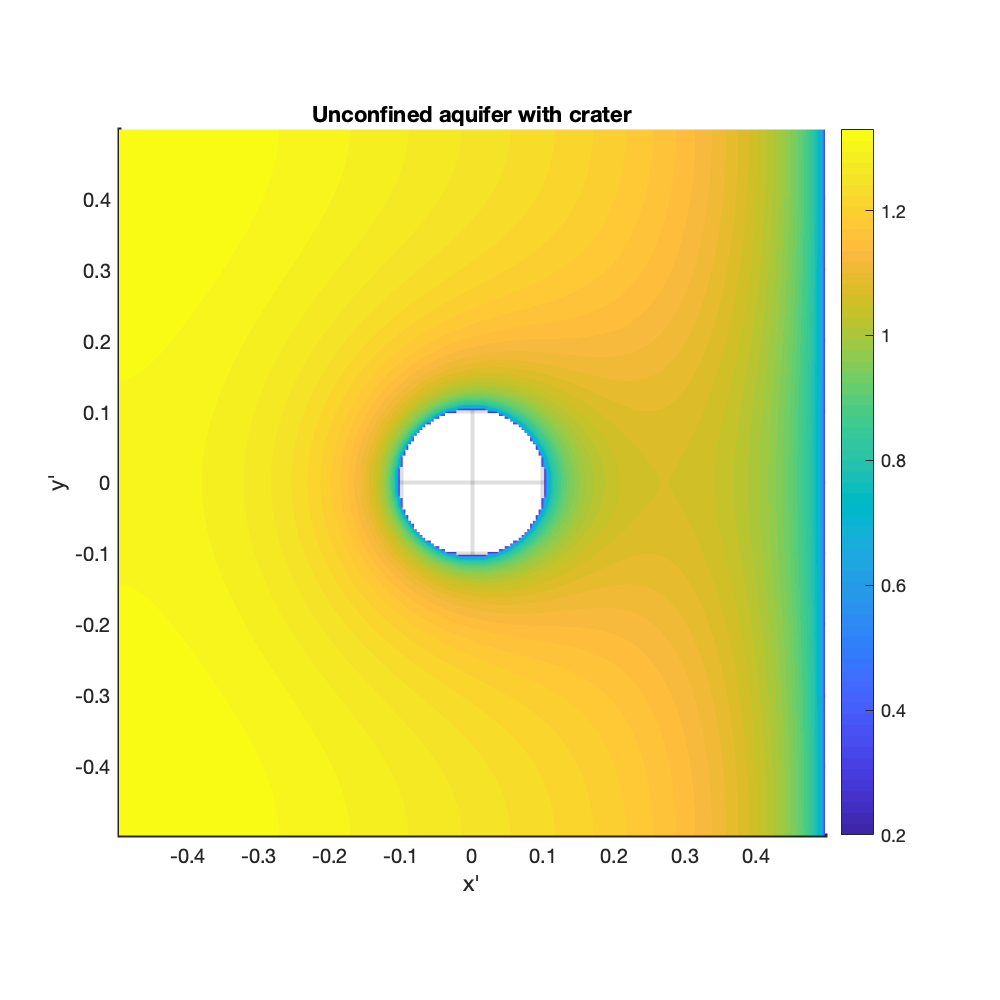


figure('position',[10 10 500 500])
surf(Xc,Yc,reshape(hD,Grid.Ny,Grid.Nx)), view(2), shading interp, colorbar
xlabel 'x'''
ylabel 'y'''
title 'Unconfined aquifer with crater'
axis equal tight

## Auxillary functions

## plot_circle()

function [] = plot_circle(x0,y0,r)
theta = linspace(0,2*pi,100);
plot(x0+r*sin(theta),y0+r*cos(theta),'r')
end

## find_crater_dofs()

function [dof_in,dof_out] = find_crater_dofs(x0,y0,r,Grid,Xc,Yc)
% Author: Euclid of Alexandria
% date: 280 BC
% Description:
% Function separates the vector of dof's into those within and outside of 
% the spacified circular grain.
% Input: 
% (x0,y0) = center of the circle
% r = radius of circle
% Grid = structure containing gris information
% Xc, Yc = Ny by Nx matrices containing the coordinates of the cell centers
% Output:
% dof_in = column vector containing dof's inside the circle
% dof_out = column vecto containing dof's outside the circle

dof_in =[];
for i = 1:length(r)
    dist_center = sqrt((x0(i)-Xc(:)).^2 + (y0(i)-Yc(:)).^2);
    dof_in = [dof_in;Grid.dof(dist_center <= r(i))];  
end
dof_in = sort(dof_in,1,'ascend');
dof_out = setdiff(Grid.dof,dof_in);
end

## steady_dupuit_res_jac()

function [res,Jac] = steady_dupuit_res_jac(Grid,D,G,M,fs,fn,n_exp)
% Function in flux term
f  = @(u) u.^(n_exp+1)/(n_exp+1);
df = @(u) u.^n_exp;

F  = @(u) spdiags(M*f(u),0,Grid.Nf,Grid.Nf);
dF = @(u) spdiags(df(u),0,Grid.N,Grid.N);

% Other 'function matrices'
GU = @(u) spdiags(G*u,0,Grid.Nf,Grid.Nf);

% Residual and Jacobian
res = @(u) D*(F(u)*G*u) + fs + fn;
Jac = @(u) D*(GU(u)*M*dF(u) + F(u)*G);
end